# Endemic equilibrium

In an SIRS model, an endemic equilibrium is a state where the *disease continue to exist* in the population at a constant level.

In case the disease completely dies out, we call it a *disease-free equilibrium*.

We are interested in finding out the steady-state values of $S, I$ and $R$ at this equilibrium.

Let us denote these steady-state values by $S^*, I^*$ and $R^*$ respectively.

It is important to note that at steady state,


$$\frac{dS}{dt} = \frac{dI}{dt} = \frac{dR}{dt} = 0$$


Thus, the rates are not changing over time anymore - the have reached a steady state!

## The steady state susceptible population $S^*$

We know


$$\frac{dI}{dt} = \beta S I - \gamma I$$


At equilibrium,


$$0 = \beta S I - \gamma I$$


For an endemic equilibrium, $I^* > 0$, thus we can divide by $I$


$$0 = \beta S - \gamma \Rightarrow S^* = \frac{\gamma}{\beta}$$


Now we define $\beta = \frac{R_0 \gamma}{N}$

Therefore, $S^* = \frac{N}{R_0}$

## Similarly we can find the expressions for $I^*$ and $R^*$


$$I^* = \frac{\alpha N}{(\alpha + \gamma)}(1 - \frac{1}{R_0})$$



$$R^*= \frac{\gamma N}{\alpha+\gamma} \left(1-\frac{1}{R_0}\right) }$$


Going back to our SIRS example:

Disease-free equilibrium is attracting: (S*,I*,R*) = (1000,0,0)


Endemic equilibrium: S* = 666.67, I* = 30.30, R* = 303.03
Endemic equilibrium: S* = 333.33, I* = 60.61, R* = 606.06


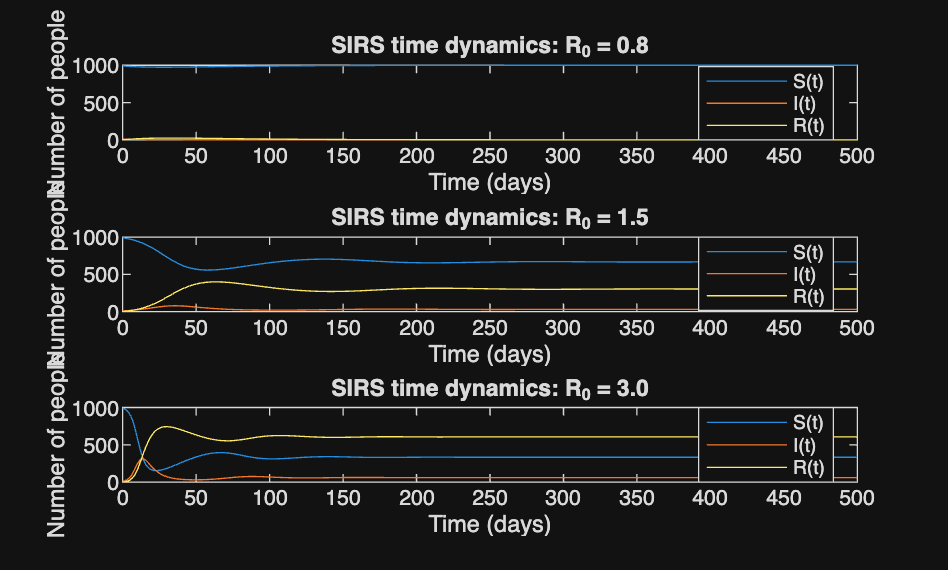

N = 1000;               
gamma = 0.20;           
alpha = 0.02; 

R0values = [0.8 1.5 3.0]; 

% Initial values
x0 = [990; 10; 0];

tspan = [0 500];

function dxdt = SIRS_ODE(x, beta, gamma, alpha)
    S = x(1); 
    I = x(2); 
    R = x(3); 
    
    dSdt = -beta*S*I + alpha*R; 
    dIdt = beta*S*I - gamma*I;
    dRdt = gamma*I - alpha*R; 
    
    dxdt = [dSdt; dIdt; dRdt];
end

for m = 1:length(R0values)
    R0 = R0values(m);
    beta = R0*gamma/N; 
    [t,x] = ode45(@(t,x) SIRS_ODE(x,beta,gamma,alpha),tspan,x0);

    S = x(:,1);
    I = x(:,2);
    R = x(:,3);

    [Imax,k] = max(I);
    tpeak = t(k);

    if R0 > 1
        Sstar = N/R0;
        Istar = alpha*N/(alpha + gamma)*(1 - 1/R0);
        Rstar = gamma*N/(alpha + gamma)*(1 - 1/R0);
        fprintf('Endemic equilibrium: S* = %.2f, I* = %.2f, R* = %.2f\n', ...
            Sstar,Istar,Rstar)
    else
        fprintf('Disease-free equilibrium is attracting: (S*,I*,R*) = (%.0f,0,0)\n',N)
    end

    subplot(length(R0values),1,m)

    plot(t,S)
    hold on
    plot(t,I)
    plot(t,R)
    xlabel('Time (days)')
    ylabel('Number of people')
    title(sprintf('SIRS time dynamics: R_0 = %.1f',R0))
    legend('S(t)','I(t)','R(t)','Location','best')
end